# Tribell Laplacian program

Computes the eigenvalues and eigenfunctions of the Laplace operator on the *Tribell *quantum graph

## Set up the graph structure and coordinates of the problem

We have to be careful here and in the next step **addTribellPlotCoords** if we want different segments to have different lengths and discretizations. The order that the edges are labeled is not necessarily the order in which they are given here.

[sources,targets]=tribellTemplate;
L1=2; L2=2*pi; L = [L1 L1 L1 L2 L2 L2];
N1 = 20; N2=64; % want N2 a multiple of four for later
N=[N1 N1 N1 N2 N2 N2];
Phi = quantumGraph(sources,targets,L,'nxVec',N);

## Set up coordinates on which to plot the solutions

Note that this requires a user-written plotting function. An alternate syntax to the line below is rewrite the call to the quantumGraph constructor above as 

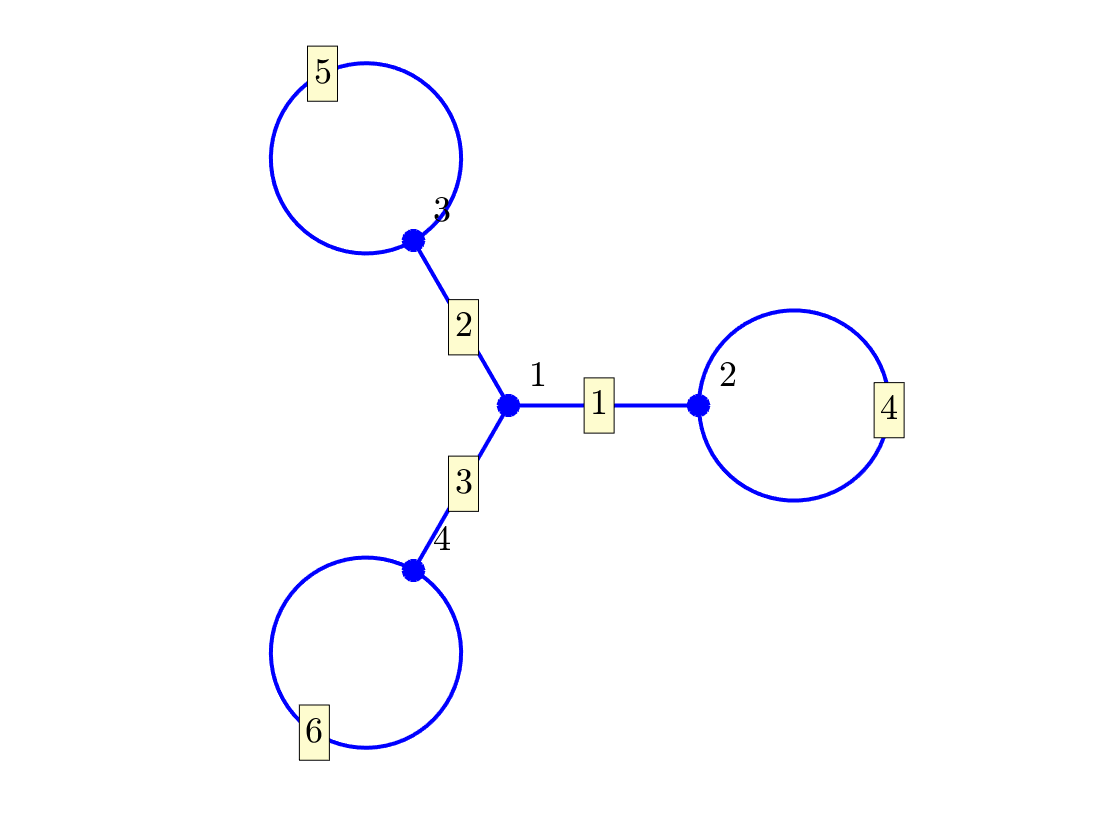

Phi.addPlotCoords(@tribellPlotCoords);
Phi.plot('layout')

## Construct the Laplacian and calculate its eigenvalues and eigenvectors

A little cleanup needed because the null eigenvalue is sometimes is calculated as positive and sometimes as negative and this screws up the sorting.

[V,lambda]=eig(Phi);
[singles,doubles,triples]=separateEigs(lambda);
nToPlot=4;

## Plot the first few multiplicity-one eigenfunctions

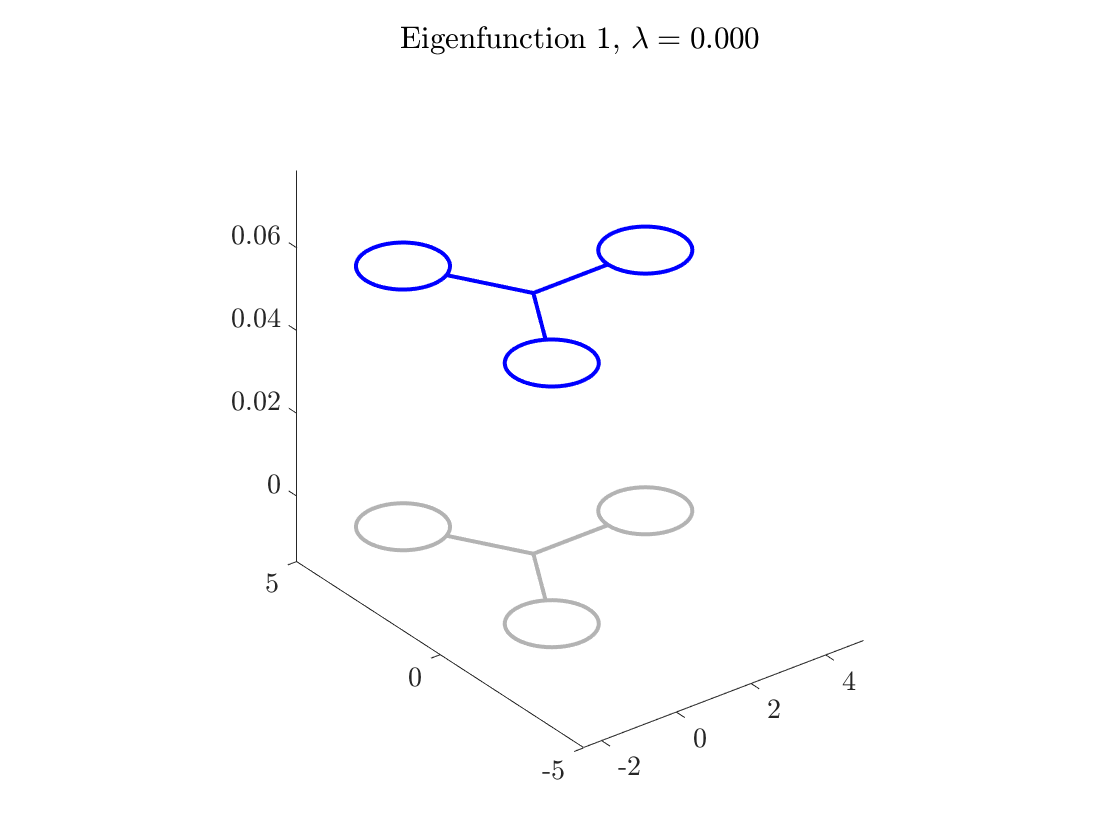

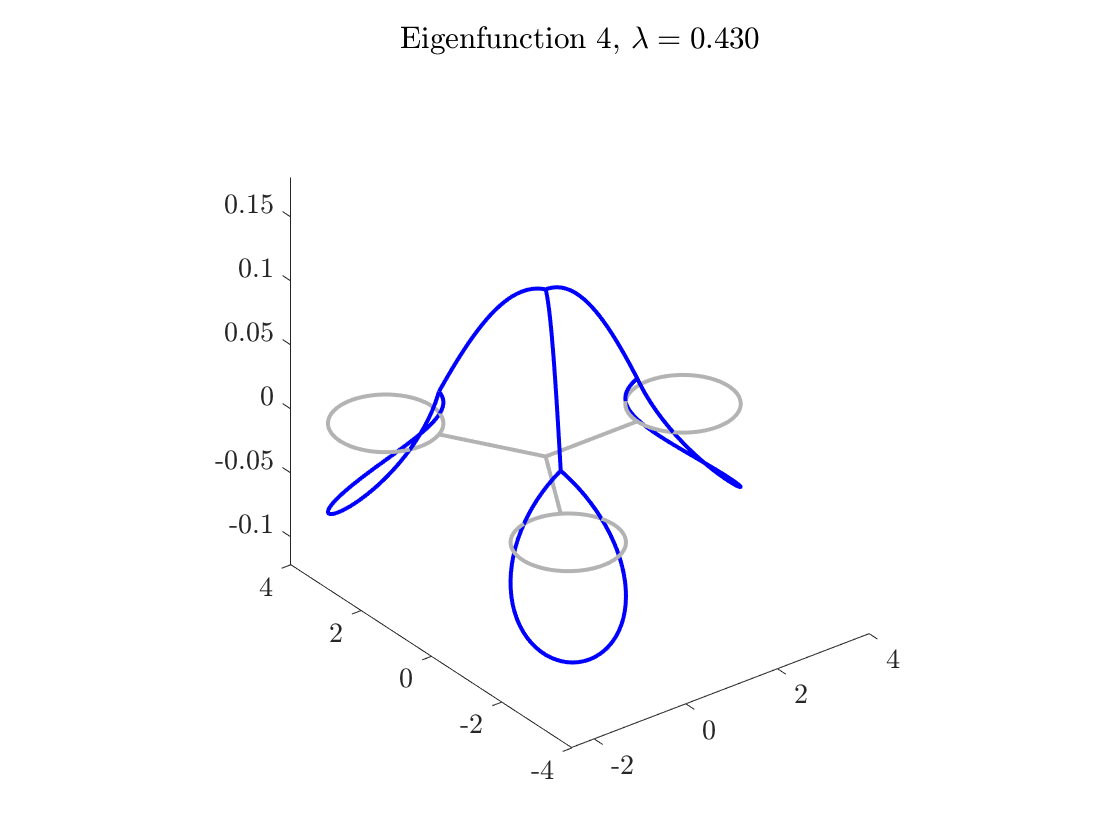

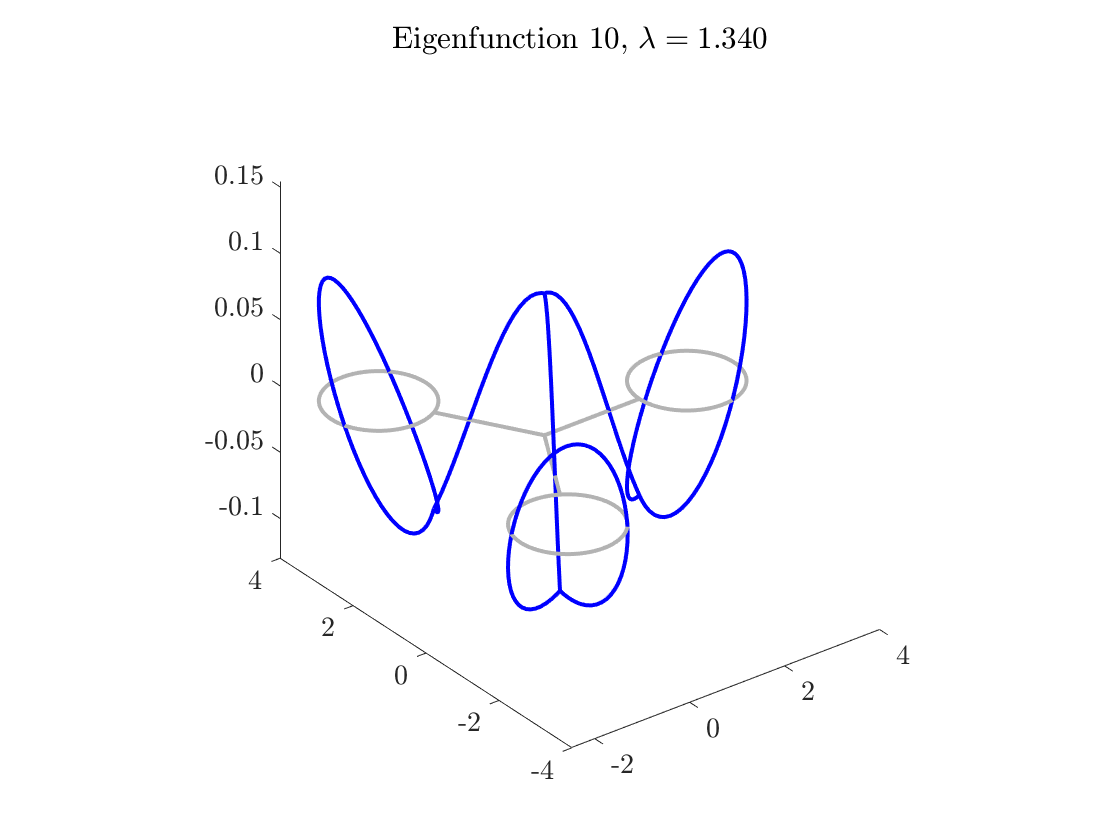

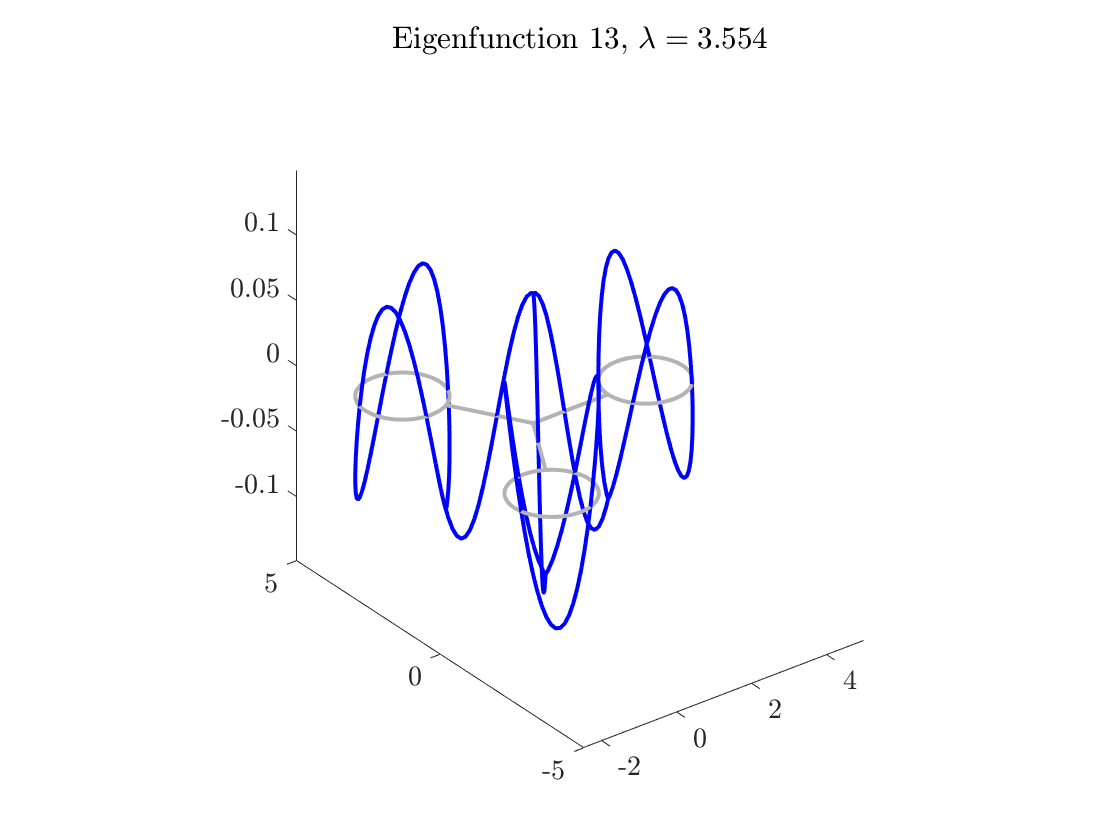

for k=1:nToPlot
    figure
    if(V(1,singles(k))<0)
        V(:,singles(k))=-V(:,singles(k));
    end
    Phi.plot(V(:,singles(k)))
    title(sprintf('Eigenfunction %i, $\\lambda = %0.3f$',singles(k), lambda(singles(k))));
end

## Plot the first few multiplicity-two eigenfunctions

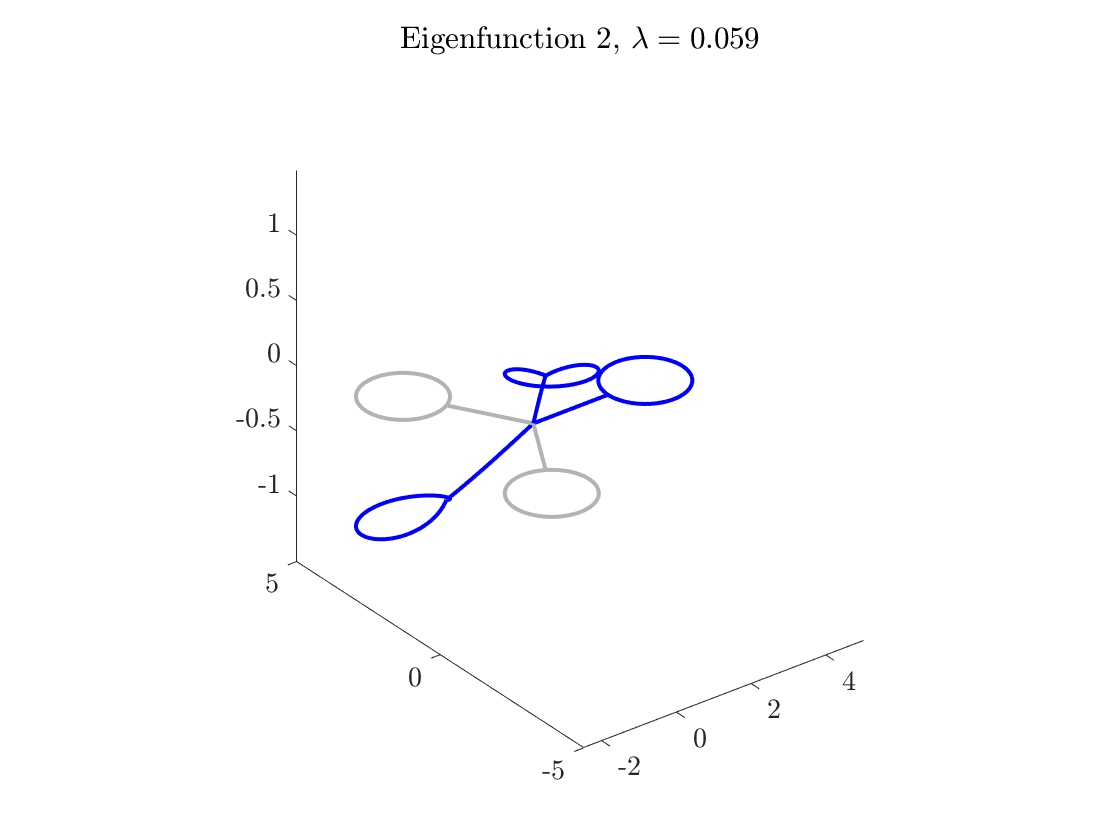

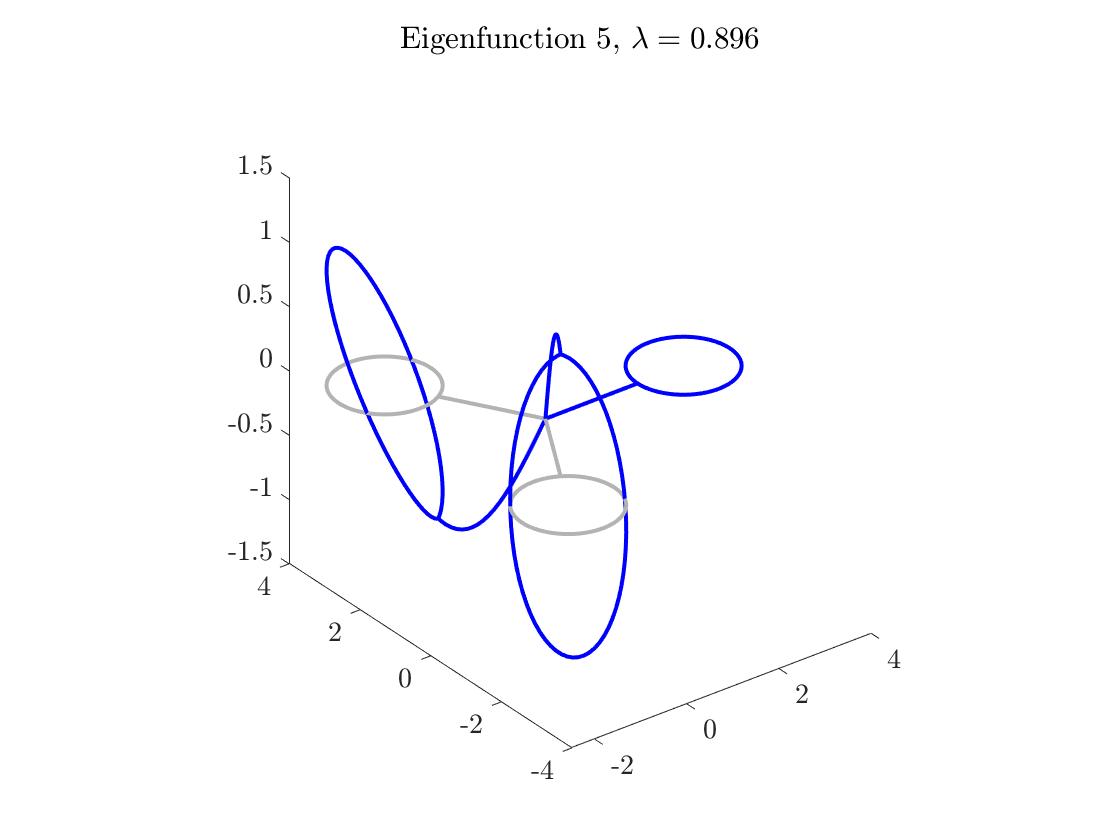

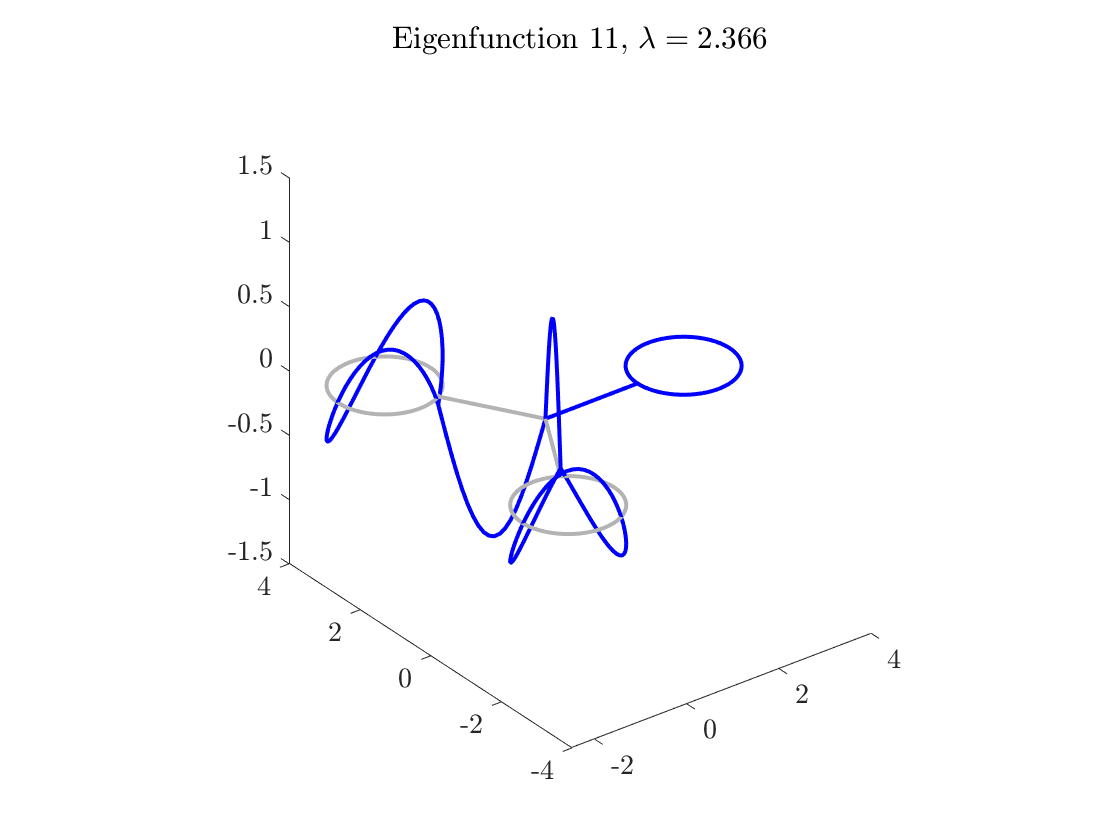

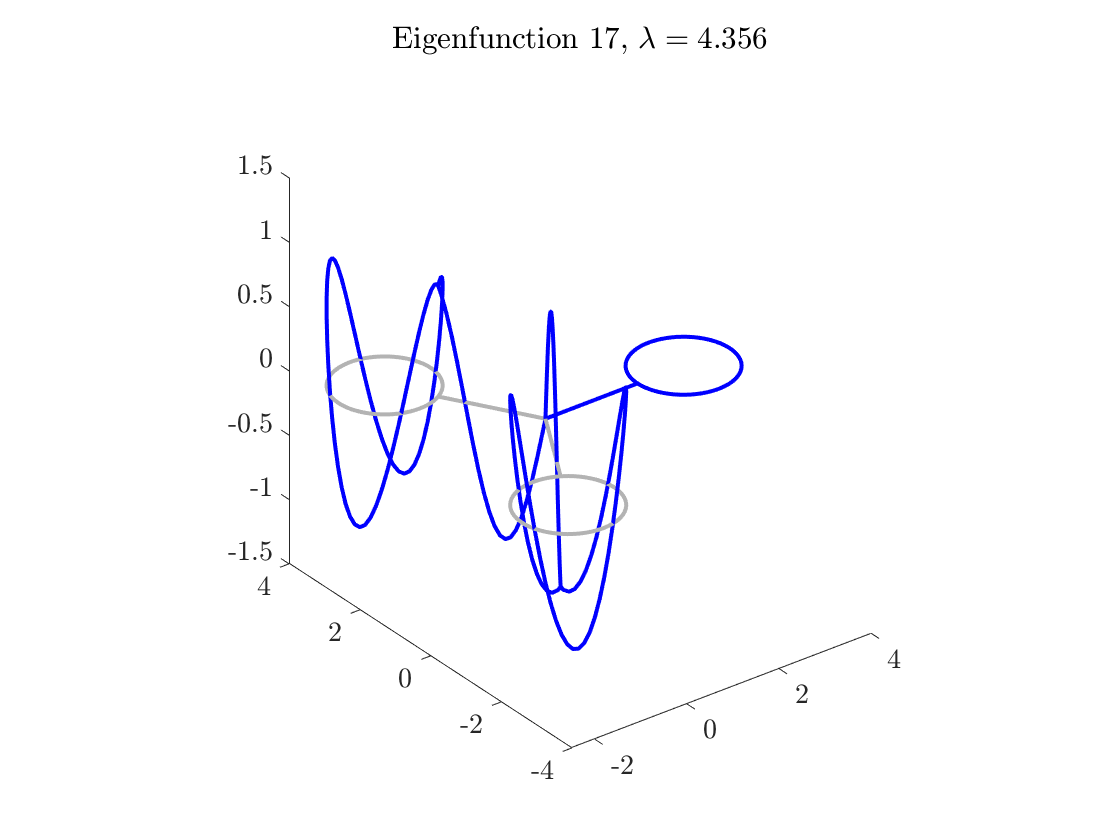

for k=1:nToPlot
    figure
    v=tribellResolveDoubles(V,doubles(k),Phi);
    Phi.plot(v{1})
    title(sprintf('Eigenfunction %i, $\\lambda = %0.3f$',doubles(k), lambda(doubles(k))));
end

## Plot the first few multiplicity-three eigenfunctions

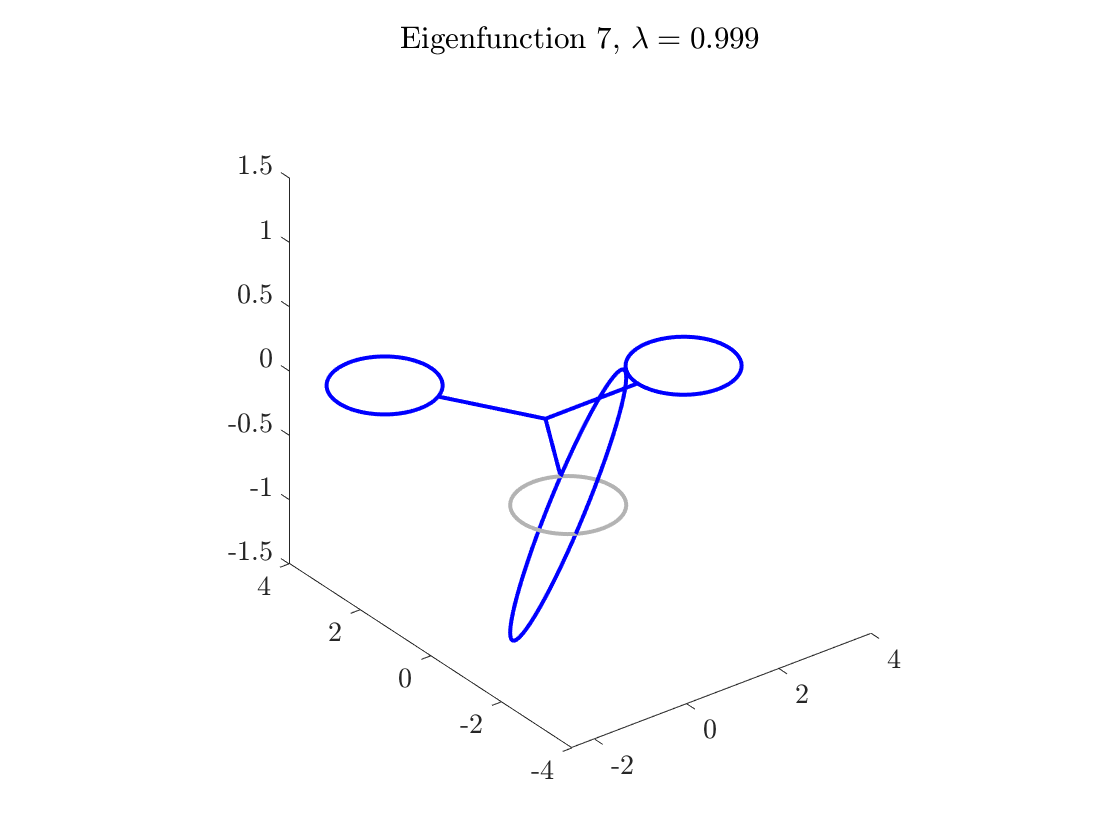

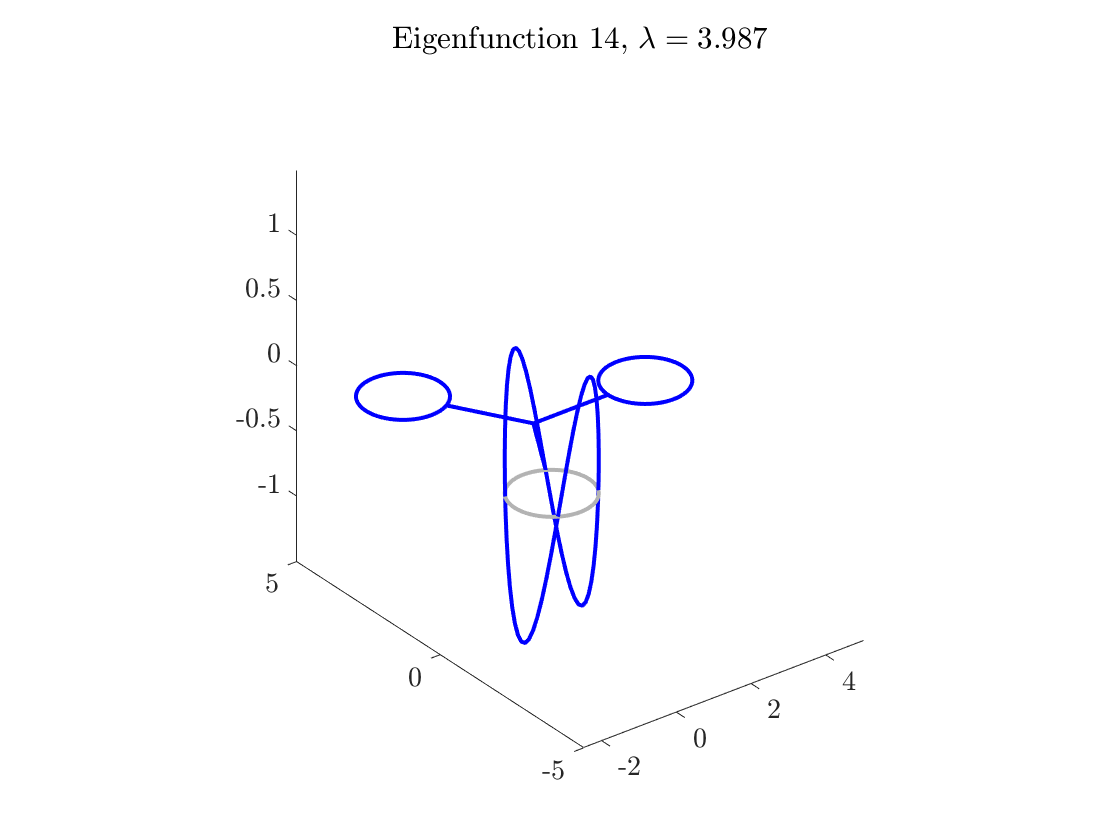

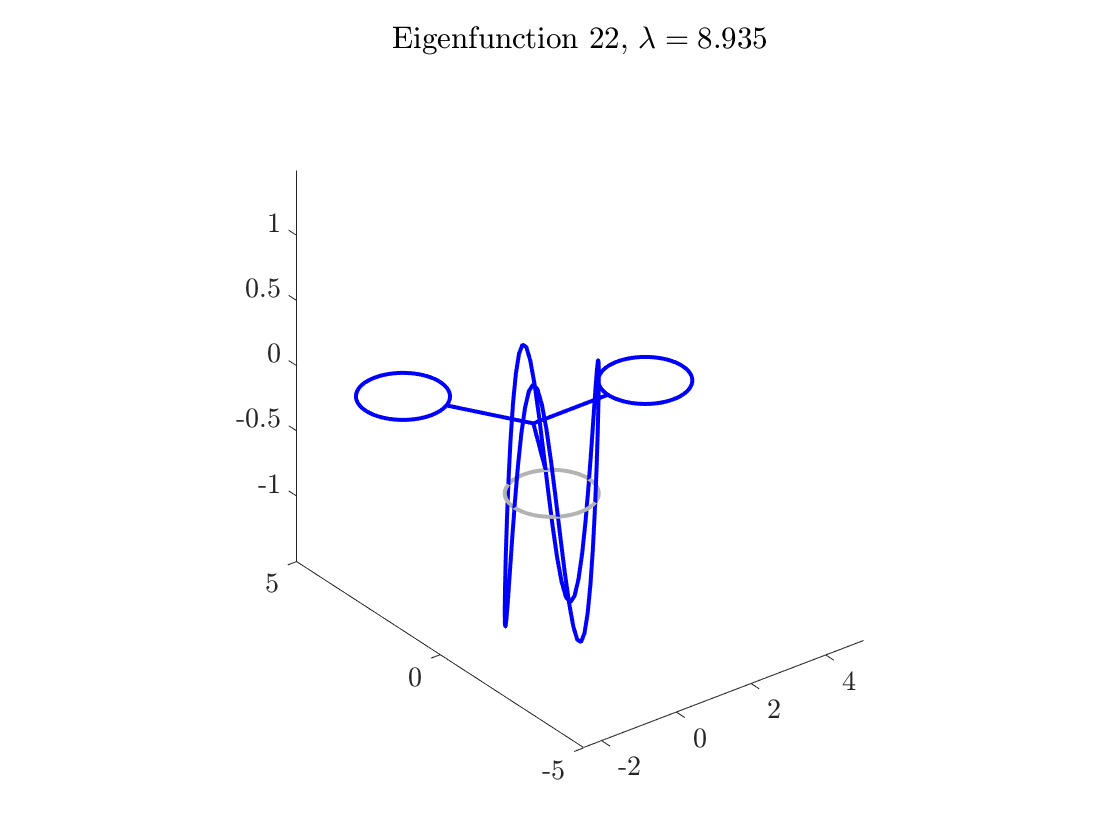

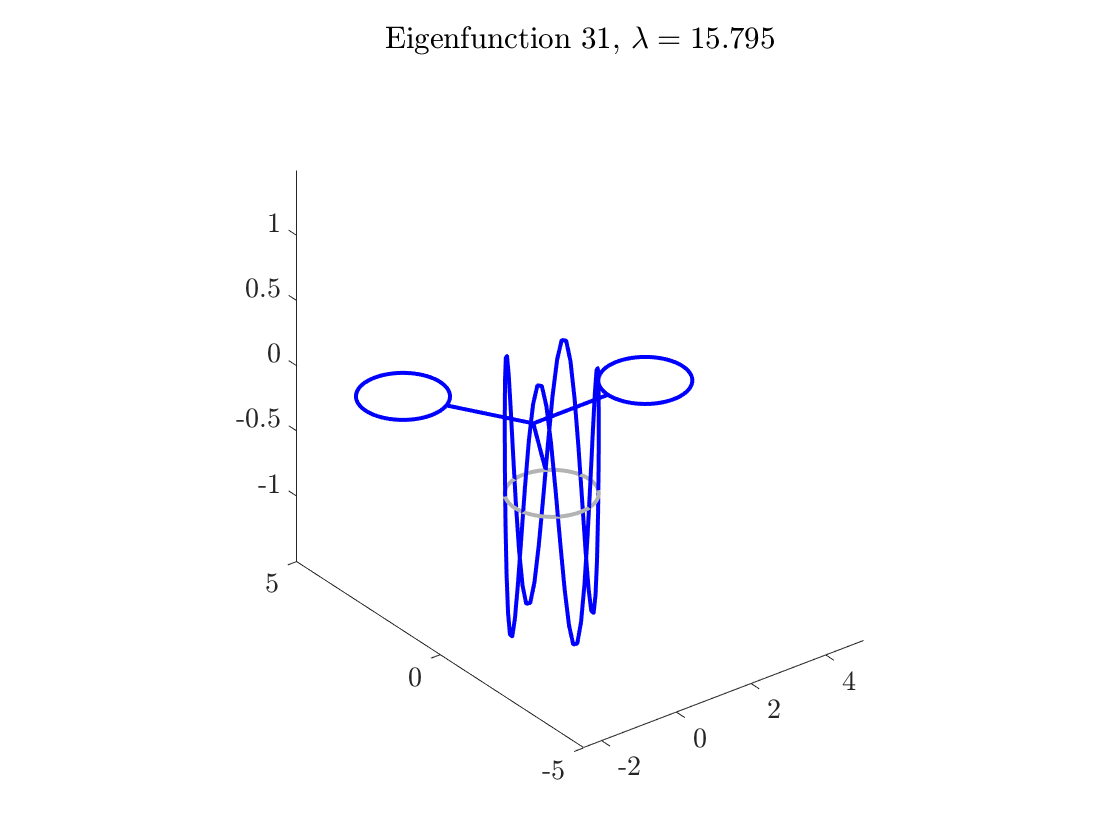

for k=1:nToPlot
    figure
    v=tribellResolveTriples(V,triples(k),Ph);
    Phi.plot(v{1})
    title(sprintf('Eigenfunction %i, $\\lambda = %0.3f$',triples(k), lambda(triples(k))));
end